Sparse Matrix

S(1,2)=10

S(3,3)=11

S(5,4)=12

i=[1 3 5];
j=[2 3 4];
values=[10 11 12];
spa=sparse(i,j,values);

full version of the sparse matrix

spaFull=full(spa);

spdiags:extract and create sparse band and diagonal matrices. Extracts all non-zero diagonals

size(A)==[m,n] => there is m+n-1 diagonals

upper diaonals are positive and lower diagonals are negative.

[B,d]=spdiags(A); B=non zero diagonals, d=non zero diagonal indicies.

A= [0 5 0 10 0 0;
    0 0 6 0 11 0;
    3 0 0 7 0 12;
    1 4 0 0 8  0;
    0 2 5 0 0  9];
[B,d]=spdiags(A);

Back to orjinal matrix

orjinalA=full(spdiags(B,d,5,6));

when the coloums of B are larger than the diagonals they are replacing

M=repmat((1:6).',[1,7]);
d=[-4 -2 -1 0 3 4 5];
A=spdiags(M,d,6,6);
fullA=full(A);
extract_d=spdiags(B,d);

fullA2=spdiags(B,d,M);

Sparsity

nnz: counts the number of nonzeros in a matrix

0<= sparsity <=1

density=nnz(A)/numel(A);
sparsity=1-density;

Diagonal Matrices

vector to diagonal matrix

d=[-3 4 2];
D=diag(d);

diagonal matrix to vector

d=diag(D);

diag(x,n)

not: diag(x,0)==diag(x)

disp(diag(d,0))

    -3     0     0
     0     4     0
     0     0     2



disp(diag(d,1))

     0    -3     0     0
     0     0     4     0
     0     0     0     2
     0     0     0     0



disp(diag(d,2))

     0     0    -3     0     0
     0     0     0     4     0
     0     0     0     0     2
     0     0     0     0     0
     0     0     0     0     0



disp(diag(d,-1))

     0     0     0     0
    -3     0     0     0
     0     4     0     0
     0     0     2     0



disp(diag(d,-2))

     0     0     0     0     0
     0     0     0     0     0
    -3     0     0     0     0
     0     4     0     0     0
     0     0     2     0     0



x=ones(4,1);
disp(diag(x(1:3),1)) %neglects last elements of x

     0     1     0     0
     0     0     1     0
     0     0     0     1
     0     0     0     0



some exaple

F=round(10*randn(3,4));
disp(diag(F));

    17
    14
    14



J=[1:4;5:8;9:12;20 0 5 4];
K=[diag(1:4) J, J.' zeros(4)]

K =      1     0     0     0     1     2     3     4     1     5     9    20     0     0     0     0
     0     2     0     0     5     6     7     8     2     6    10     0     0     0     0     0
     0     0     3     0     9    10    11    12     3     7    11     5     0     0     0     0
     0     0     0     4    20     0     5     4     4     8    12     4     0     0     0     0


disp(nnz(K))

    34



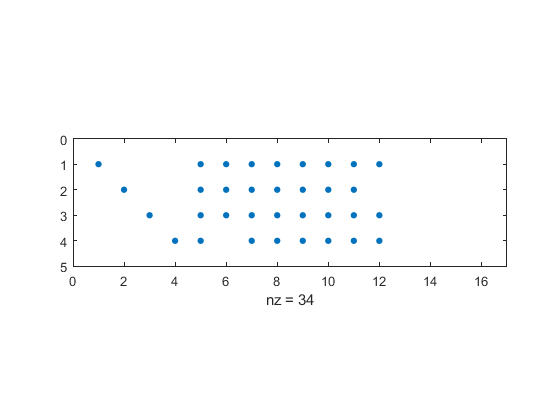

spy(K) %plot number of non-zero K elements

x=0:0.1:0.5;
y1=4*sin(3*x);
y2=3*sin(4*x);
tabulating=[x.' y1.' y2.'];

Example

x=2*ones(3,1);
y=-2*ones(4,1);
disp(diag(y,0));

    -2     0     0     0
     0    -2     0     0
     0     0    -2     0
     0     0     0    -2



disp(diag(x,1));

     0     2     0     0
     0     0     2     0
     0     0     0     2
     0     0     0     0



A=diag(y,0)+diag(x,1);
disp(A);

    -2     2     0     0
     0    -2     2     0
     0     0    -2     2
     0     0     0    -2

